# Displays

**Chapter Title:** Visual Encoding 

**Book Title:  Circadian rhythms**

**Chapter Authors:** Wandell, Brainard, Cottaris 

**Book Editor**: Spitschan

**    Figure 3. RGB file to radiance-display model. **ISETBio converts rgb data from an image file into a spectral scene representation by assuming the image will be shown on a calibrated display. The two images render the same data with respect to two different displays. The image at the upper is rendered assuming a specific calibrated LCD. The graphical inset shows the mean spectral radiance in a small region (white rectangle). The image at the lower right (Reflectance) shows the rendering on a theoretical display designed to produce scene radiance similar to natural data. Notice that slight differences in colors, particularly of the plants. Differences of this magnitude are typical of the variation observed between different calibrated displays.

N.B. To run this code, your Matlab path must include ISETBio

## SceneFromFile demonstration

displayName = 'LCD-Apple';
scene = sceneFromFile('woodDuck.png','rgb',100,displayName);
sceneWindow(scene);
% imagescRGB(sceneGet(scene,'rgb'));

Use this code to pick a rectangular region from the scene Window.

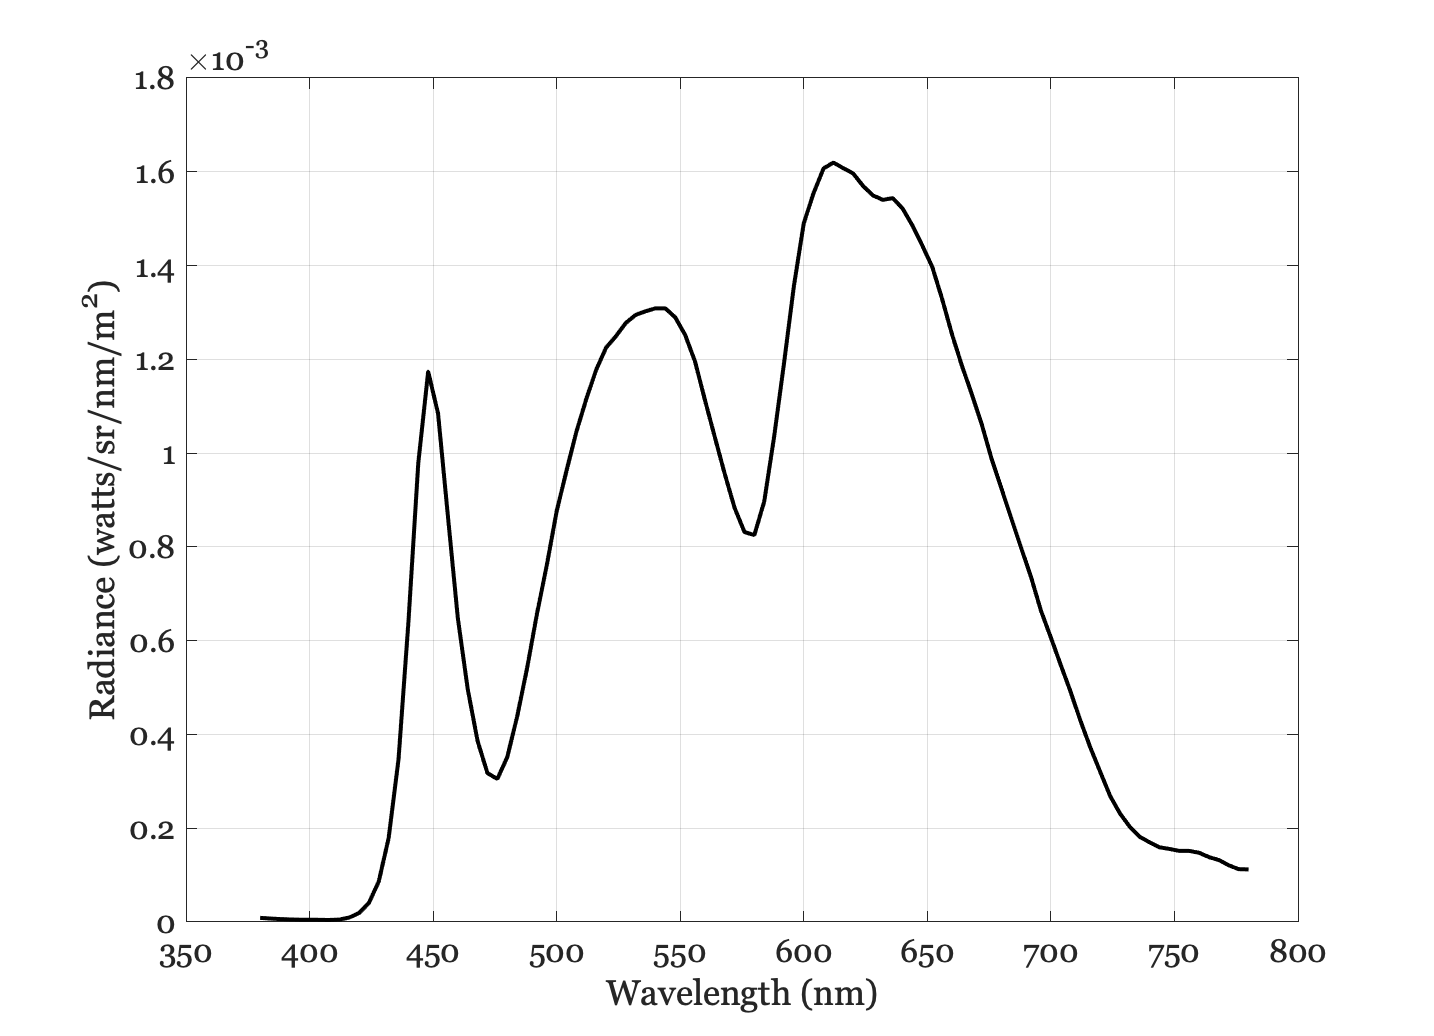

rect = [193 93 120 190];   % RECT from the chapter
scenePlot(scene,'radiance energy roi',rect);
thisAx = gca;
thisAx.Children.LineWidth = 2;
thisAx.Children.Color = 'k';

## The special display that creates natural radiance spectra

The display is built for D65 illuminant

displayName = 'reflectance-display';
scene = sceneFromFile('woodDuck.png','rgb',100,displayName);

Assigning the spatial dixel from LCD-Apple to the reflectance-display.


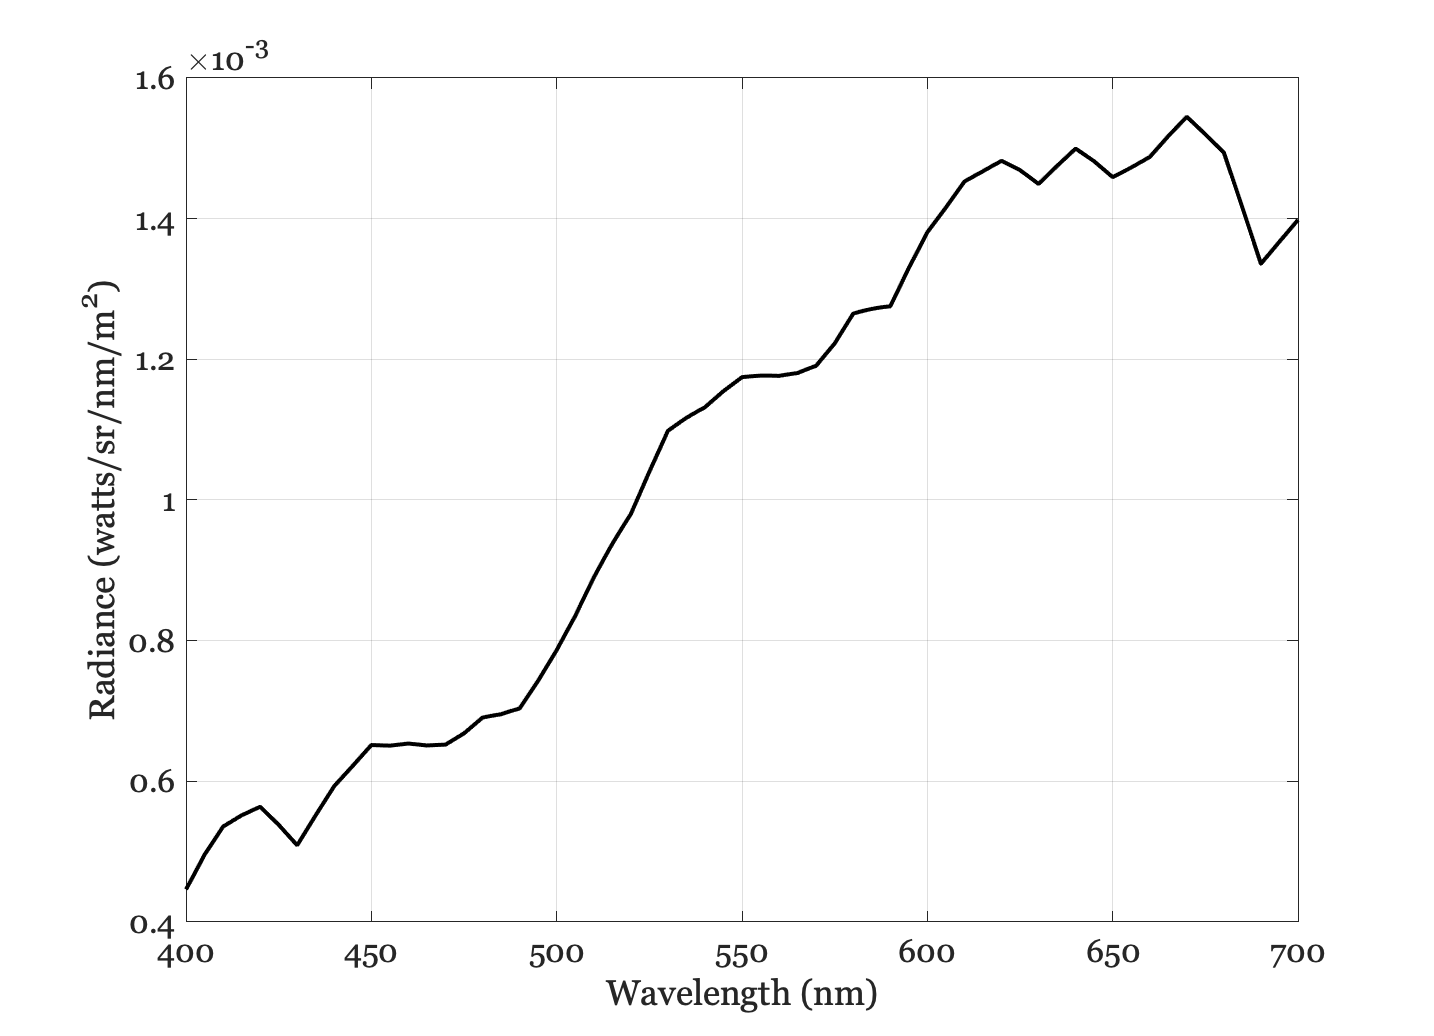

sceneWindow(scene);
% imagescRGB(sceneGet(scene,'rgb'));
scenePlot(scene,'radiance energy roi',rect);
thisAx = gca;
thisAx.Children.LineWidth = 2;
thisAx.Children.Color = 'k';

## Now a  typical Samsung OLED display

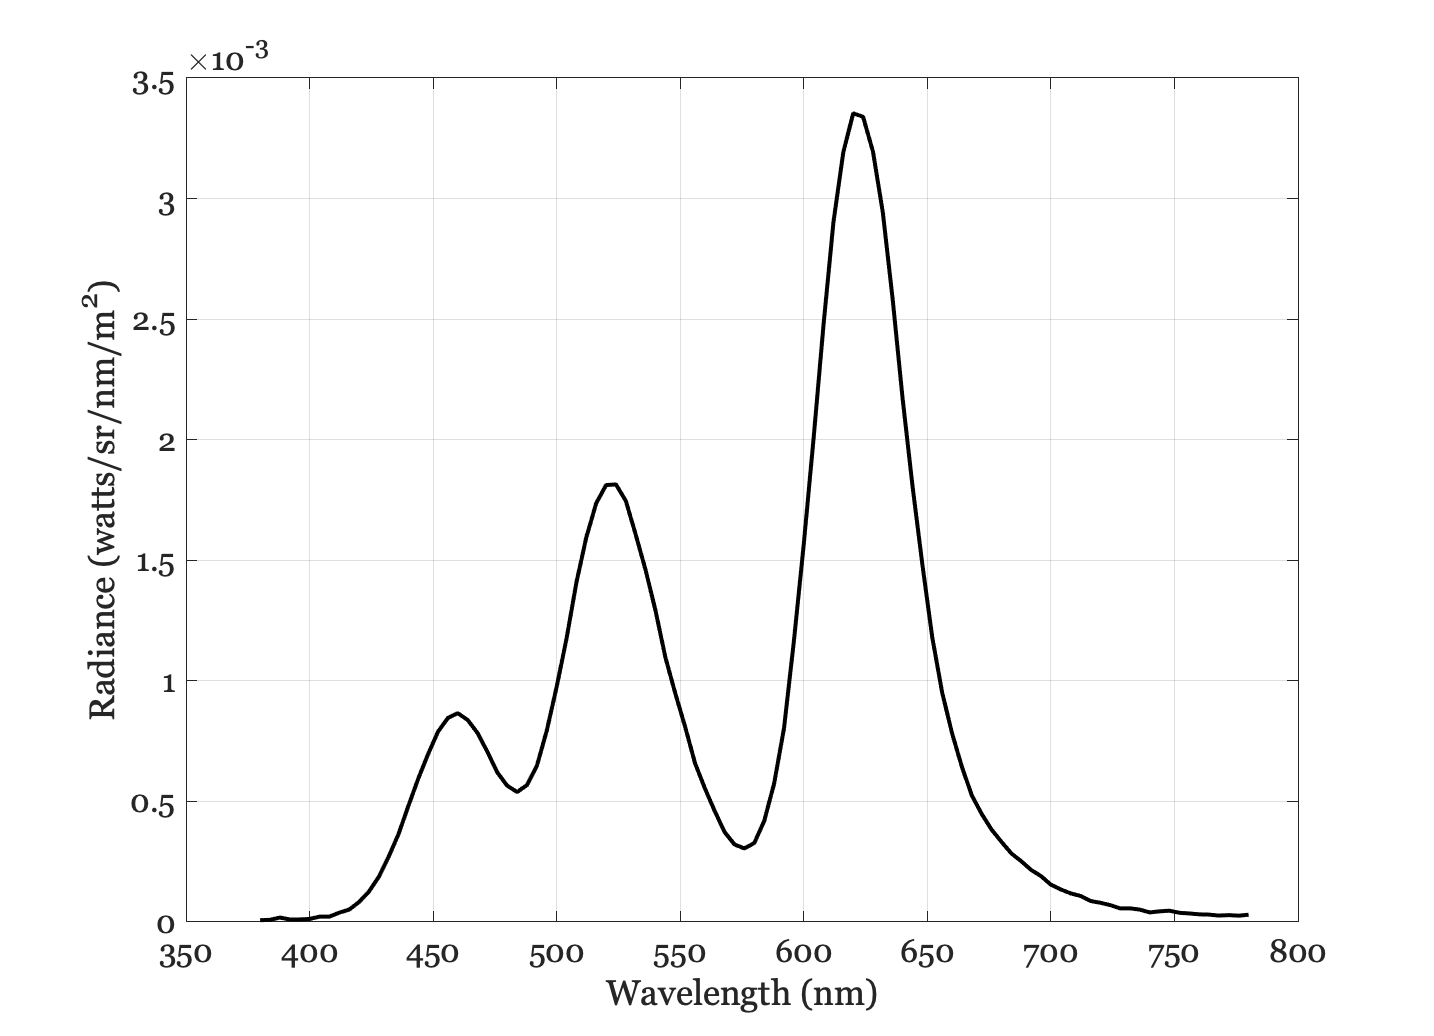

displayName = 'OLED-Samsung';
scene = sceneFromFile('woodDuck.png','rgb',100,displayName);
sceneWindow(scene);
% imagescRGB(sceneGet(scene,'rgb'));
scenePlot(scene,'radiance energy roi',rect);
thisAx = gca;
thisAx.Children.LineWidth = 2;
thisAx.Children.Color = 'k';

## Now properties of the display primaries

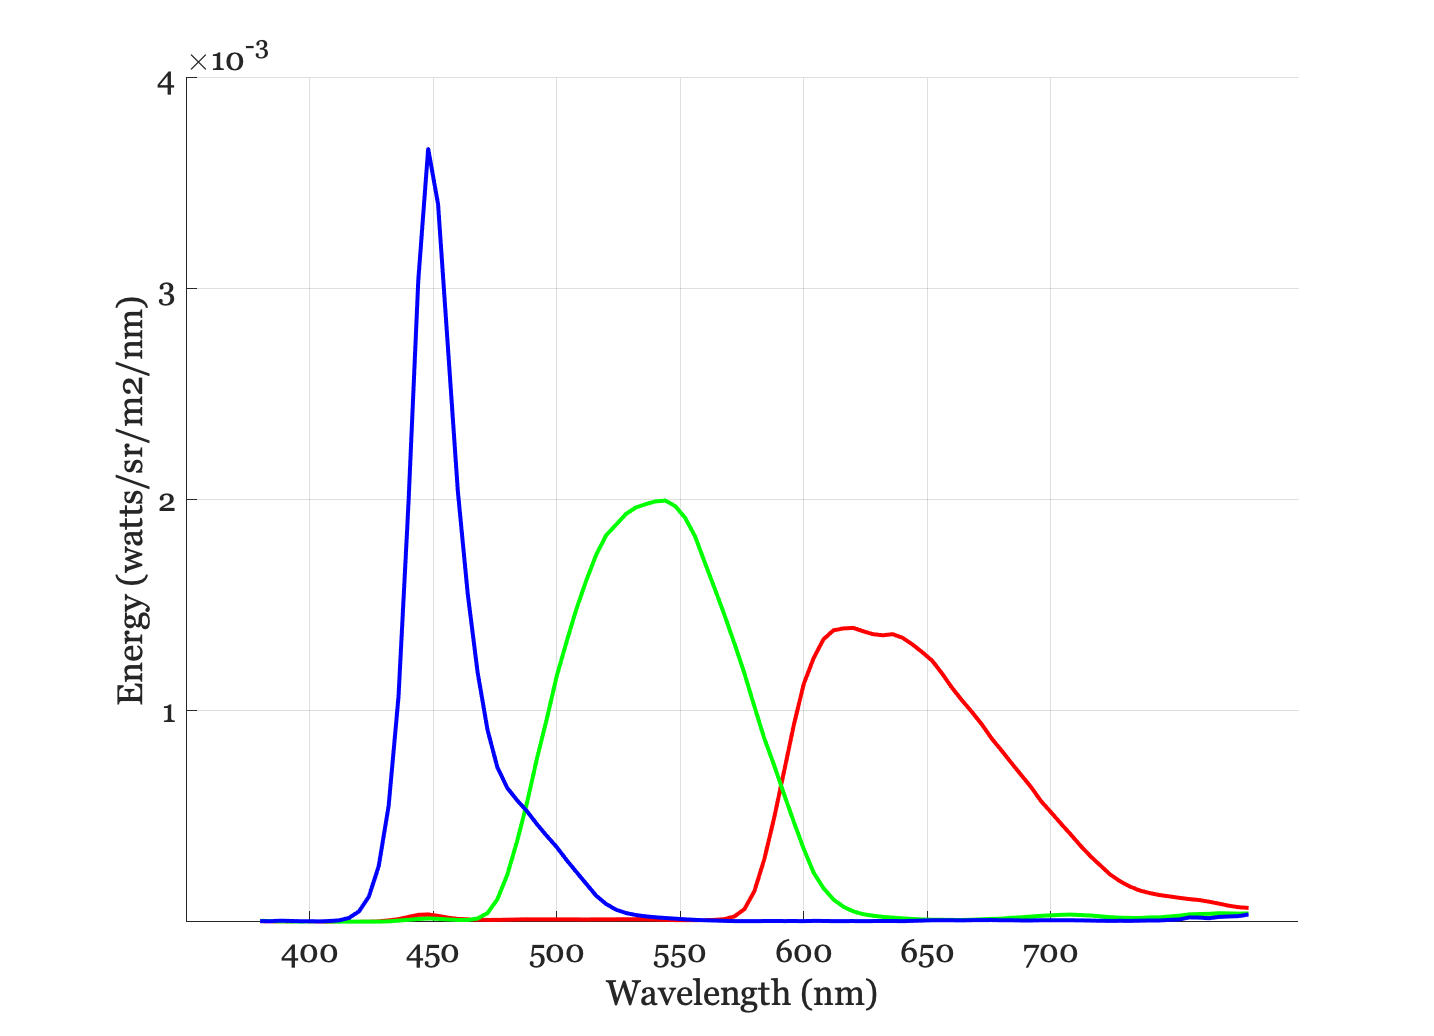

wave = 400:1:700;
wSamples = 400:50:700;
displayName = 'LCD-Apple';
thisDisplay = displayCreate(displayName);
displayPlot(thisDisplay,'spd');
set(gca,'xtick',wSamples,'ytick',(1:4)*1e-3);

displayName = 'reflectance-display';
thisDisplay = displayCreate(displayName);

Assigning the spatial dixel from LCD-Apple to the reflectance-display.


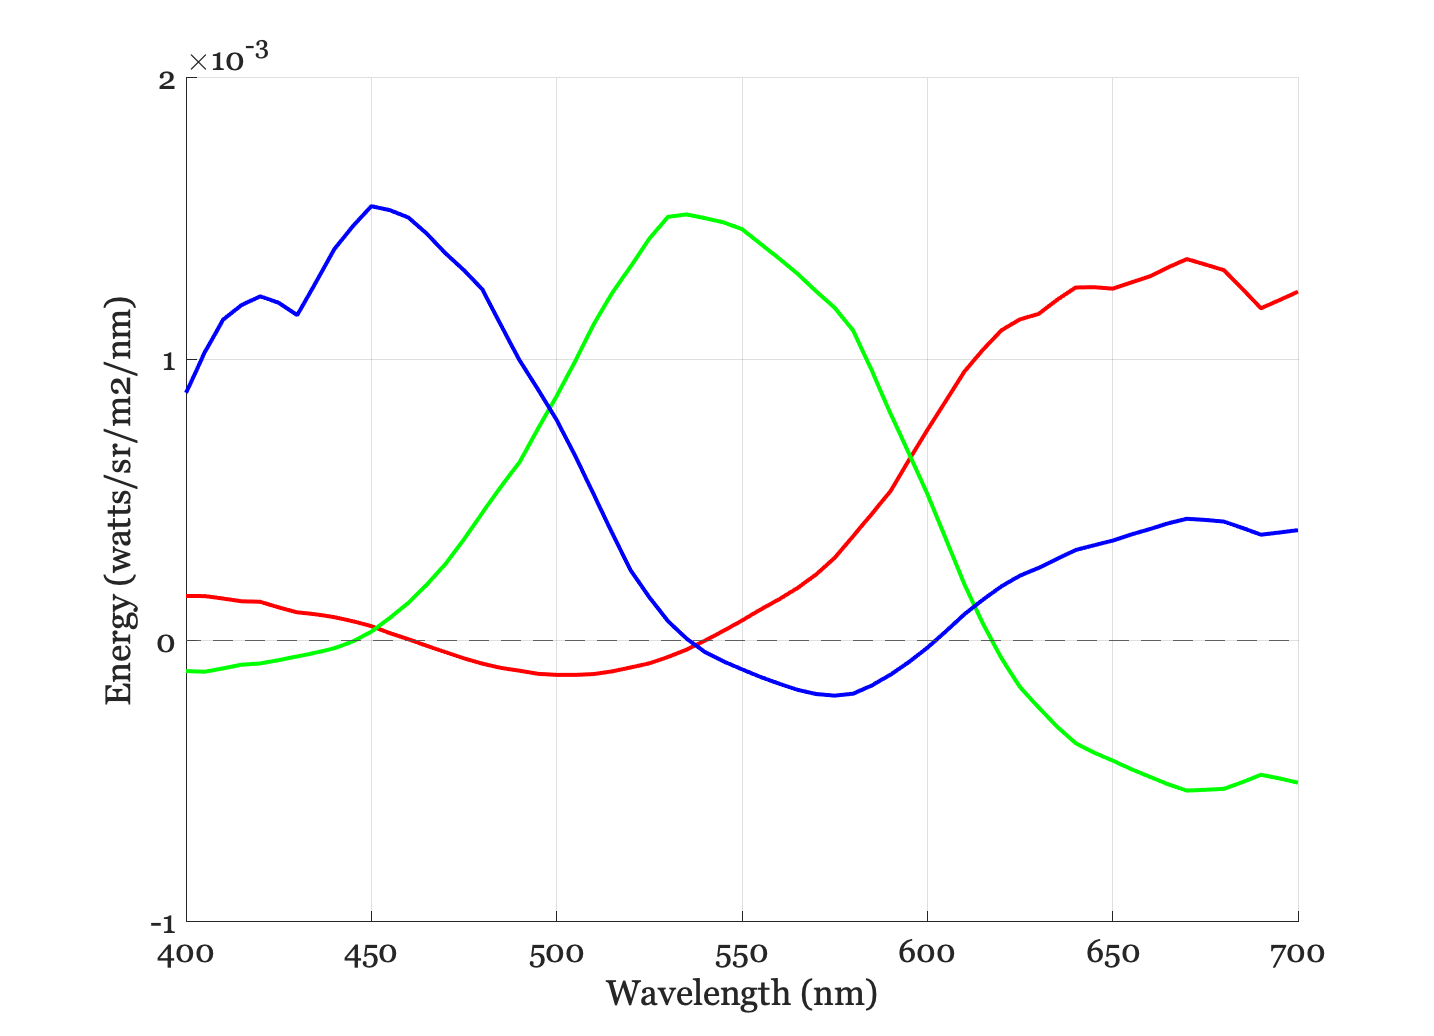

displayPlot(thisDisplay,'spd');
set(gca,'xtick',wSamples,'ytick',(-1:4)*1e-3);
p = xaxisLine;
p.LineWidth = 0.5;

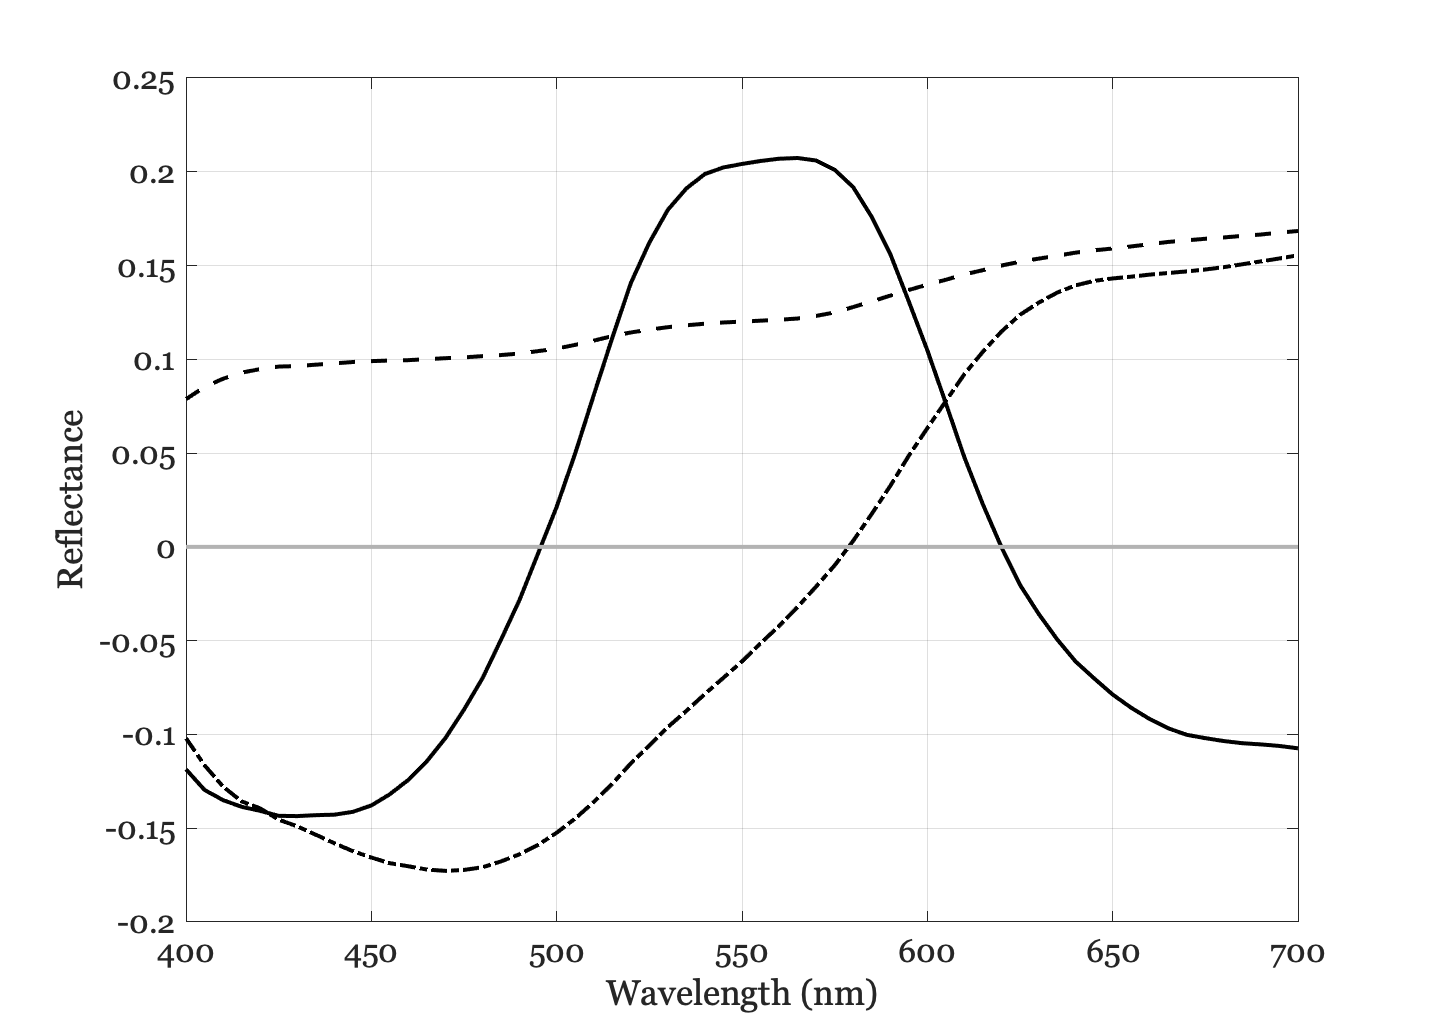


basis = ieReadSpectra('reflectanceBasis.mat',wave);
basis(:,1) = -1*basis(:,1);
hdl = plotReflectance(wave,basis(:,1:3));

thisAx = get(hdl,'CurrentAxes'); p = thisAx.Children;
p(1).Color = 'k';
p(2).Color = 'k'; p(2).LineStyle = '-.';
p(3).Color = 'k'; p(3).LineStyle = '--';

thisLine = xaxisLine;
lineShade = [0.7 0.7 0.7];
thisLine.LineWidth = 2; thisLine.LineStyle = '-'; thisLine.Color = lineShade;
title('');

Here is the daylight spectral power distribution.

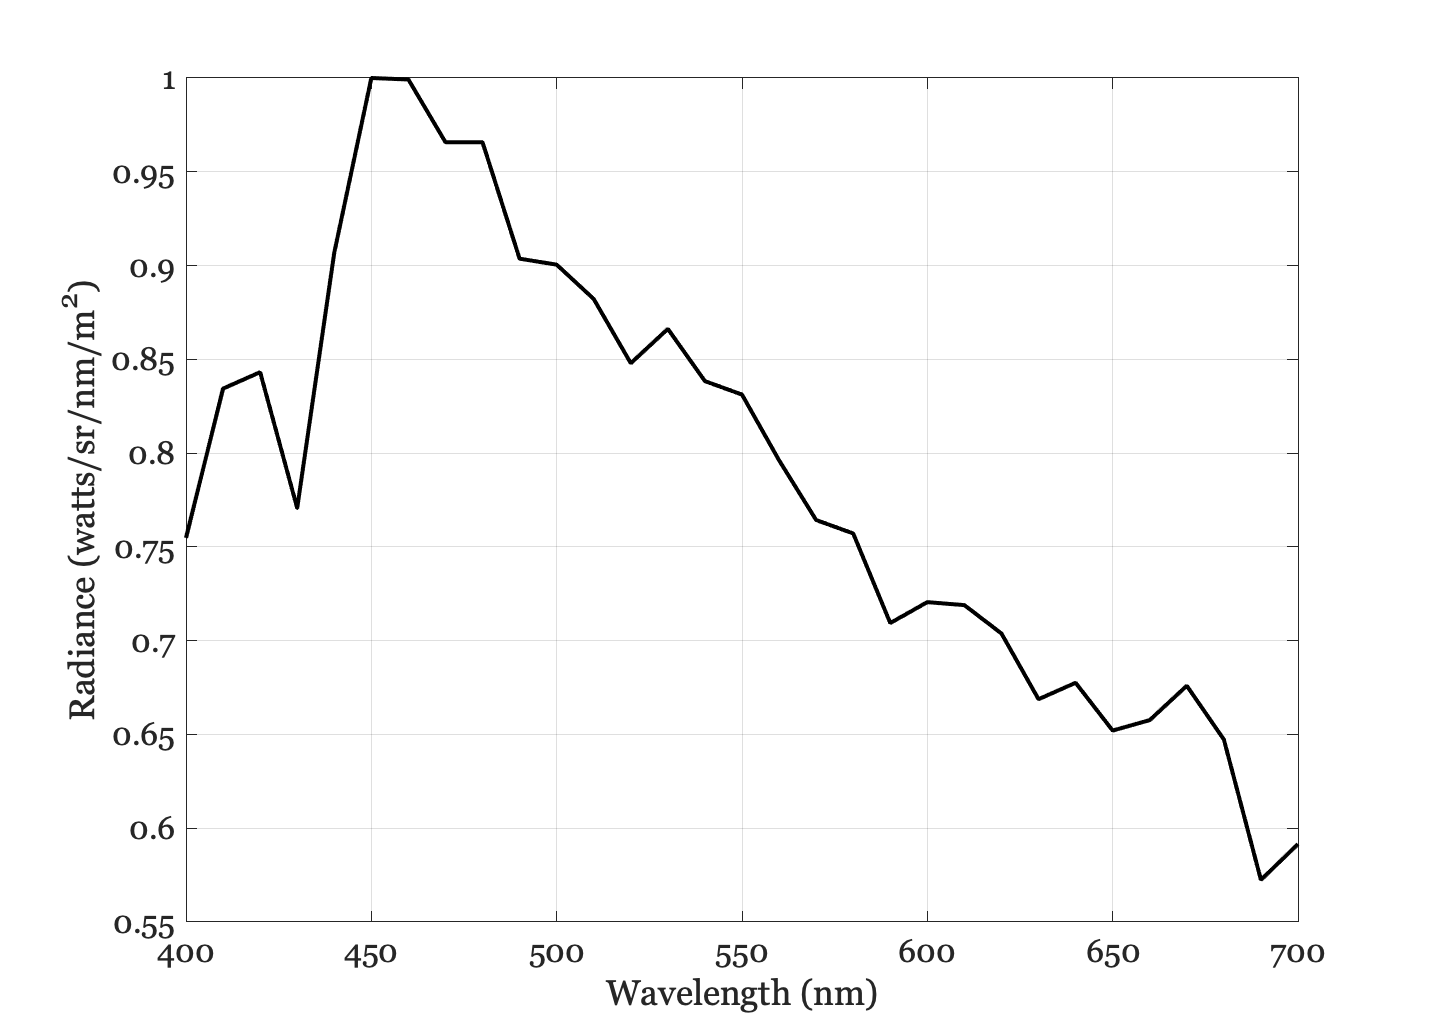

day = ieReadSpectra('cieDaylightBasis.mat',wave);
day = day(:,1)/max(day(:,1));
hdl = plotRadiance(wave,day);
thisAx = get(hdl,'CurrentAxes'); p = thisAx.Children;
for ii=1:numel(p)
    p(ii).Color = 'k';
end
title('');